asdasd

clear all
clc
close all


asdasd

dim = 128

dim = 128

x=linspace(1,dim,dim)

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



signal = 1000

signal = 1000


PulseOpt.slope = dim/100

PulseOpt = struct with fields:
    slope: 1.2800



b1_func = signal*fermi_pulse(x, dim, PulseOpt)

b1_func = 	1.0e+03 *

    0.0022    0.0048    0.0103    0.0223    0.0475    0.0982    0.1921    0.3419    0.5315    0.7125    0.8441    0.9220    0.9627    0.9826    0.9919    0.9963    0.9983    0.9992    0.9996    0.9998    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


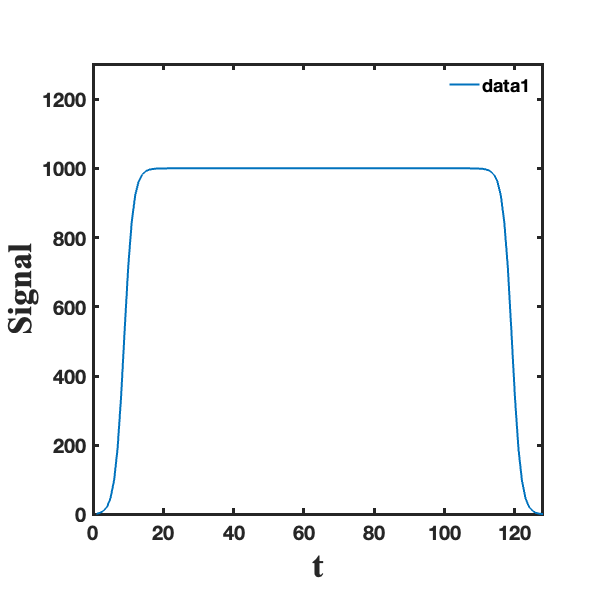

structHandler.figure = figure(1);
plot(x,b1_func, 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)

Filter

gauss_b1 = filter_map()

gauss_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


gauss_b1.options.Smoothingfilter_Type = 'gaussian'

gauss_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


gauss_b1.options.Smoothingfilter_Dimension = '2D'

gauss_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


data.Raw = repmat(b1_func, dim, 1)

data = struct with fields:
    Raw: [128×128 double]



fwhm_vox = 3

fwhm_vox = 3


gauss_b1.options.Smoothingfilter_sizex = fwhm_vox

gauss_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


gauss_b1.options.Smoothingfilter_sizey = fwhm_vox

gauss_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


gauss_b1.options.Smoothingfilter_sizez = fwhm_vox

gauss_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]



fit_results = gauss_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


Plot

gauss_b1_1d = fit_results.Filtered(1,:)

gauss_b1_1d = 	1.0e+03 *

    0.0039    0.0076    0.0160    0.0337    0.0682    0.1304    0.2298    0.3668    0.5262    0.6810    0.8067    0.8934    0.9454    0.9734    0.9875    0.9942    0.9973    0.9988    0.9994    0.9997    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


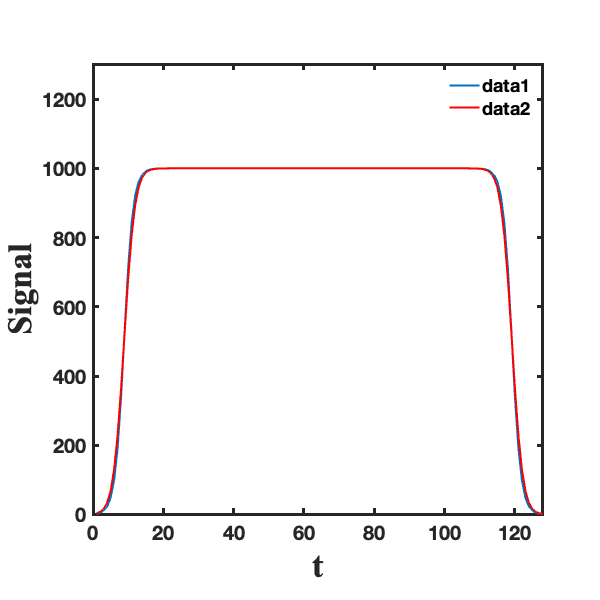


structHandler.figure = figure(2);
plot(x,b1_func, 'LineWidth', 2), axis([0 128 0 1300])

hold on
plot(x,gauss_b1_1d, 'r', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Plotly interactive fig: change the fwhm with a slider. Here's the case for 10 voxels:

Filter

gauss_b1 = filter_map()

gauss_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


gauss_b1.options.Smoothingfilter_Type = 'gaussian'

gauss_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


gauss_b1.options.Smoothingfilter_Dimension = '2D'

gauss_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


data.Raw = repmat(b1_func, dim, 1)

data = struct with fields:
    Raw: [128×128 double]



fwhm_vox = 10

fwhm_vox = 10


gauss_b1.options.Smoothingfilter_sizex = fwhm_vox

gauss_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


gauss_b1.options.Smoothingfilter_sizey = fwhm_vox

gauss_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


gauss_b1.options.Smoothingfilter_sizez = fwhm_vox

gauss_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]



fit_results = gauss_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


Plot

gauss_b1_1d = fit_results.Filtered(1,:)

gauss_b1_1d = 	1.0e+03 *

    0.0431    0.0688    0.1038    0.1493    0.2055    0.2720    0.3474    0.4290    0.5138    0.5979    0.6779    0.7507    0.8141    0.8670    0.9091    0.9412    0.9643    0.9798    0.9894    0.9947    0.9975    0.9988    0.9995    0.9997    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


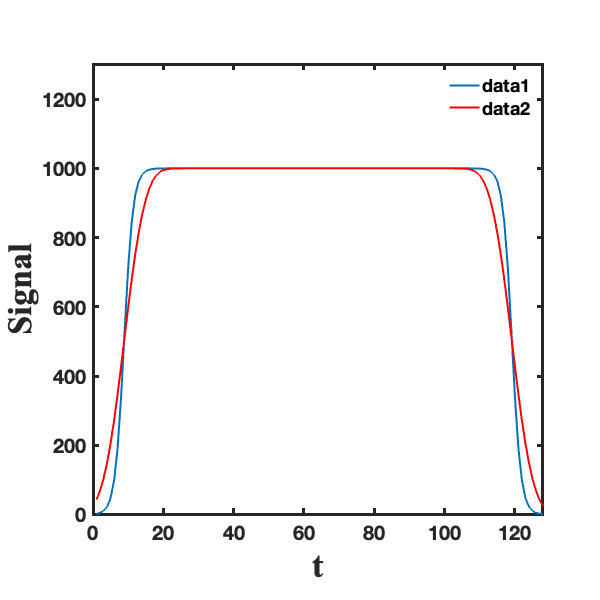


structHandler.figure = figure(3);
plot(x,b1_func, 'LineWidth', 2), axis([0 128 0 1300])

hold on
plot(x,gauss_b1_1d, 'r', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Now, plot all four with fwhm 10

filt_b1 = filter_map()

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


data.Raw = repmat(b1_func, dim, 1)

data = struct with fields:
    Raw: [128×128 double]



fwhm_vox = 10

fwhm_vox = 10


filt_b1.options.Smoothingfilter_sizex = fwhm_vox

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


filt_b1.options.Smoothingfilter_sizey = fwhm_vox

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


filt_b1.options.Smoothingfilter_sizez = fwhm_vox

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]



filt_b1.options.Smoothingfilter_Dimension = '2D'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]



filt_b1.options.Smoothingfilter_Type = 'gaussian'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


fit_results = filt_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


gauss_b1_1d = fit_results.Filtered(1,:)

gauss_b1_1d = 	1.0e+03 *

    0.0431    0.0688    0.1038    0.1493    0.2055    0.2720    0.3474    0.4290    0.5138    0.5979    0.6779    0.7507    0.8141    0.8670    0.9091    0.9412    0.9643    0.9798    0.9894    0.9947    0.9975    0.9988    0.9995    0.9997    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



filt_b1.options.Smoothingfilter_Type = 'median'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


fit_results = filt_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


median_b1_1d = fit_results.Filtered(1,:)

median_b1_1d = 	1.0e+03 *

         0         0         0    0.0022    0.0048    0.0103    0.0223    0.0475    0.0982    0.1921    0.3419    0.5315    0.7125    0.8441    0.9220    0.9627    0.9826    0.9919    0.9963    0.9983    0.9992    0.9996    0.9998    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



filt_b1.options.Smoothingfilter_Type = 'polynomial'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


fit_results = filt_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


polynomial_b1_1d = fit_results.Filtered(1,:)

polynomial_b1_1d = 	1.0e+03 *

   -0.2551   -0.1112    0.0200    0.1394    0.2478    0.3458    0.4344    0.5141    0.5856    0.6496    0.7066    0.7572    0.8020    0.8413    0.8757    0.9056    0.9314    0.9535    0.9723    0.9881    1.0011    1.0118    1.0202    1.0268    1.0317    1.0352    1.0373    1.0384    1.0385    1.0379    1.0366    1.0348    1.0325    1.0299    1.0271    1.0241    1.0210    1.0178    1.0147    1.0116    1.0086    1.0058    1.0030    1.0005    0.9981    0.9958    0.9938    0.9920    0.9904    0.9889



filt_b1.options.Smoothingfilter_Type = 'spline'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


fit_results = filt_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


spline_b1_1d = fit_results.Filtered(1,:)

spline_b1_1d = 	1.0e+03 *

   -0.0159   -0.0117   -0.0003    0.0241    0.0690    0.1416    0.2455    0.3773    0.5243    0.6682    0.7919    0.8855    0.9479    0.9842    1.0018    1.0079    1.0081    1.0060    1.0036    1.0017    1.0005    0.9999    0.9997    0.9997    0.9997    0.9998    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Plot

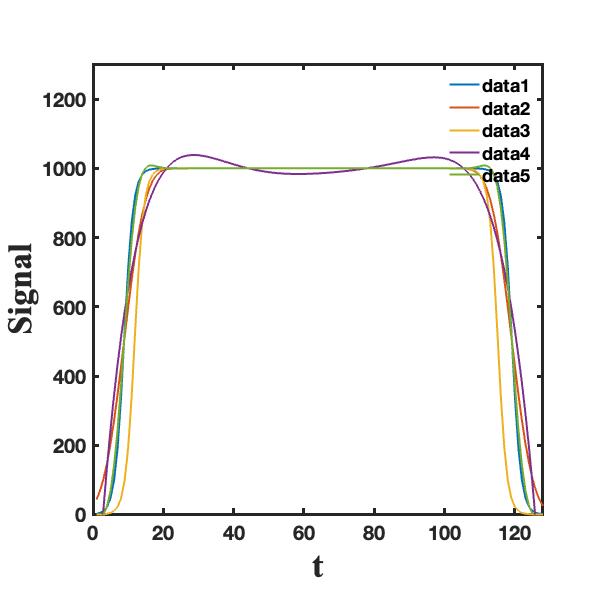


structHandler.figure = figure(4);
plot(x,b1_func, 'LineWidth', 2), axis([0 128 0 1300])

hold on
plot(x,gauss_b1_1d, 'LineWidth', 2), axis([0 128 0 1300])
plot(x,median_b1_1d, 'LineWidth', 2), axis([0 128 0 1300])
plot(x,polynomial_b1_1d, 'LineWidth', 2), axis([0 128 0 1300])
plot(x,spline_b1_1d, 'LineWidth', 2), axis([0 128 0 1300])


structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Noise case

SNR = 50

SNR = 50

noise_b1= addNoise(b1_func, SNR)

noise_b1 = 	1.0e+03 *

    0.0242    0.0289    0.0245    0.0137    0.0207    0.1127    0.2222    0.3164    0.4877    0.7416    0.8428    0.9456    0.9825    0.9585    0.9835    0.9798    1.0023    1.0226    1.0011    0.9578    1.0248    1.0004    0.9913    0.9586    1.0075    1.0049    1.0070    0.9785    0.9854    0.9821    1.0358    0.9837    0.9961    0.9826    1.0185    0.9998    1.0015    1.0194    1.0135    1.0159    0.9575    1.0045    1.0195    1.0071    1.0183    1.0425    1.0252    0.9775    0.9834    0.9981


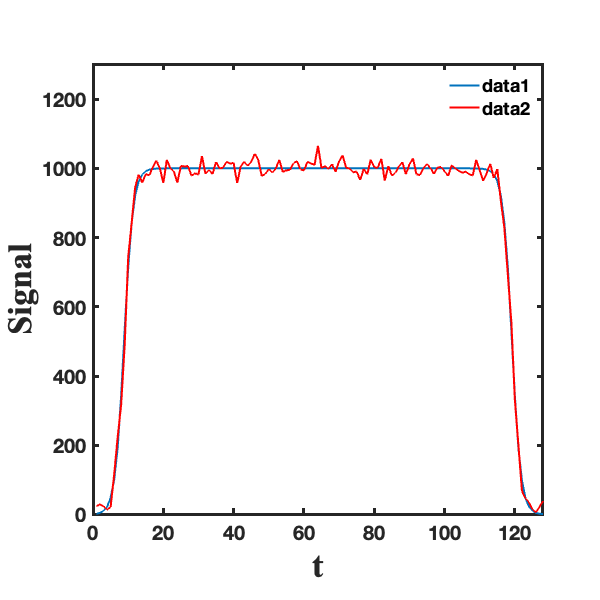


structHandler.figure = figure(5);
plot(x,b1_func, 'LineWidth', 2), axis([0 128 0 1300])

hold on
plot(x,noise_b1, 'r', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Drop down plotly for each filter method

filt_b1 = filter_map()

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


data.Raw = repmat(noise_b1, dim, 1)

data = struct with fields:
    Raw: [128×128 double]



fwhm_vox = 5

fwhm_vox = 5


filt_b1.options.Smoothingfilter_sizex = fwhm_vox

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


filt_b1.options.Smoothingfilter_sizey = fwhm_vox

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


filt_b1.options.Smoothingfilter_sizez = fwhm_vox

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]



filt_b1.options.Smoothingfilter_Dimension = '2D'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


Gauss

filt_b1.options.Smoothingfilter_Type = 'gaussian'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


fit_results = filt_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


filt_b1_1d = fit_results.Filtered(1,:)

filt_b1_1d = 	1.0e+03 *

    0.0253    0.0288    0.0389    0.0617    0.1050    0.1736    0.2690    0.3875    0.5193    0.6504    0.7657    0.8548    0.9156    0.9528    0.9737    0.9856    0.9927    0.9962    0.9970    0.9966    0.9955    0.9942    0.9930    0.9926    0.9932    0.9943    0.9942    0.9941    0.9944    0.9957    0.9969    0.9977    0.9984    0.9998    1.0020    1.0042    1.0057    1.0062    1.0050    1.0031    1.0024    1.0043    1.0080    1.0120    1.0143    1.0132    1.0090    1.0033    0.9985    0.9966


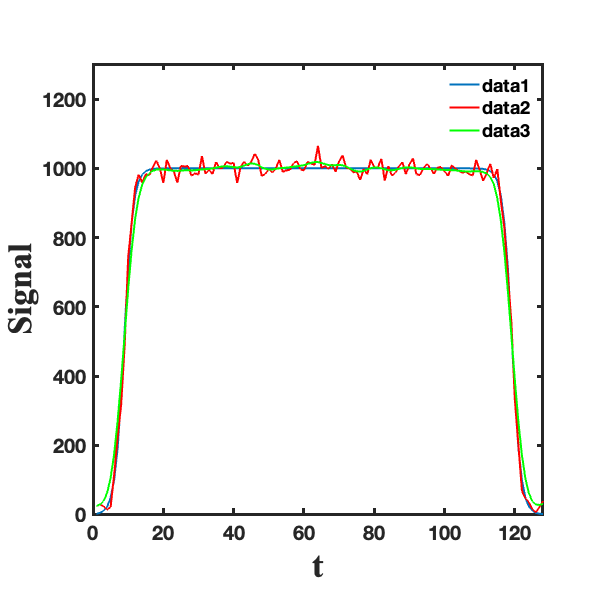


structHandler.figure = figure(6);
plot(x,b1_func, 'LineWidth', 2), axis([0 128 0 1300])

hold on
plot(x,noise_b1, 'r', 'LineWidth', 2), axis([0 128 0 1300])
plot(x,filt_b1_1d, 'g', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Median

filt_b1.options.Smoothingfilter_Type = 'median'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


fit_results = filt_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


filt_b1_1d = fit_results.Filtered(1,:)

filt_b1_1d = 	1.0e+03 *

         0         0    0.0137    0.0137    0.0137    0.0137    0.0207    0.1127    0.2222    0.3164    0.4877    0.7416    0.8428    0.9456    0.9585    0.9585    0.9798    0.9578    0.9578    0.9578    0.9578    0.9578    0.9586    0.9586    0.9586    0.9586    0.9785    0.9785    0.9785    0.9785    0.9821    0.9821    0.9826    0.9826    0.9826    0.9826    0.9998    0.9998    0.9575    0.9575    0.9575    0.9575    0.9575    1.0045    1.0071    0.9775    0.9775    0.9775    0.9775    0.9775


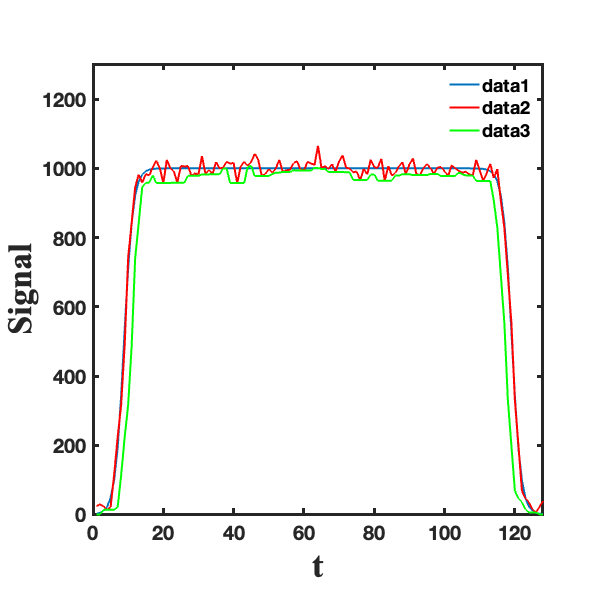


structHandler.figure = figure(7);
plot(x,b1_func, 'LineWidth', 2), axis([0 128 0 1300])

hold on
plot(x,noise_b1, 'r', 'LineWidth', 2), axis([0 128 0 1300])
plot(x,filt_b1_1d, 'g', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Poly

filt_b1.options.Smoothingfilter_Type = 'polynomial'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


fit_results = filt_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


filt_b1_1d = fit_results.Filtered(1,:)

filt_b1_1d = 	1.0e+03 *

   -0.2385   -0.0979    0.0303    0.1471    0.2531    0.3492    0.4360    0.5142    0.5845    0.6474    0.7035    0.7534    0.7976    0.8366    0.8707    0.9004    0.9262    0.9484    0.9673    0.9832    0.9965    1.0074    1.0163    1.0232    1.0286    1.0325    1.0351    1.0366    1.0373    1.0371    1.0363    1.0349    1.0331    1.0310    1.0286    1.0261    1.0234    1.0207    1.0179    1.0152    1.0126    1.0100    1.0076    1.0053    1.0031    1.0011    0.9993    0.9977    0.9962    0.9949


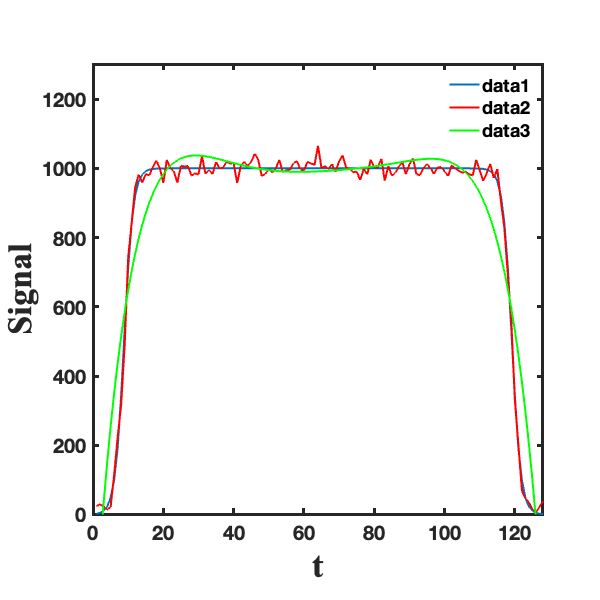


structHandler.figure = figure(8);
plot(x,b1_func, 'LineWidth', 2), axis([0 128 0 1300])

hold on
plot(x,noise_b1, 'r', 'LineWidth', 2), axis([0 128 0 1300])
plot(x,filt_b1_1d, 'g', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Spline

filt_b1.options.Smoothingfilter_Type = 'spline'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


fit_results = filt_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


filt_b1_1d = fit_results.Filtered(1,:)

filt_b1_1d = 	1.0e+03 *

    0.0026    0.0036    0.0093    0.0275    0.0685    0.1403    0.2431    0.3723    0.5199    0.6687    0.7958    0.8909    0.9512    0.9831    0.9985    1.0047    1.0068    1.0059    1.0019    0.9979    0.9967    0.9944    0.9918    0.9907    0.9928    0.9944    0.9943    0.9931    0.9933    0.9952    0.9977    0.9976    0.9979    0.9993    1.0023    1.0045    1.0062    1.0070    1.0056    1.0028    1.0007    1.0036    1.0088    1.0134    1.0165    1.0161    1.0105    1.0023    0.9968    0.9949


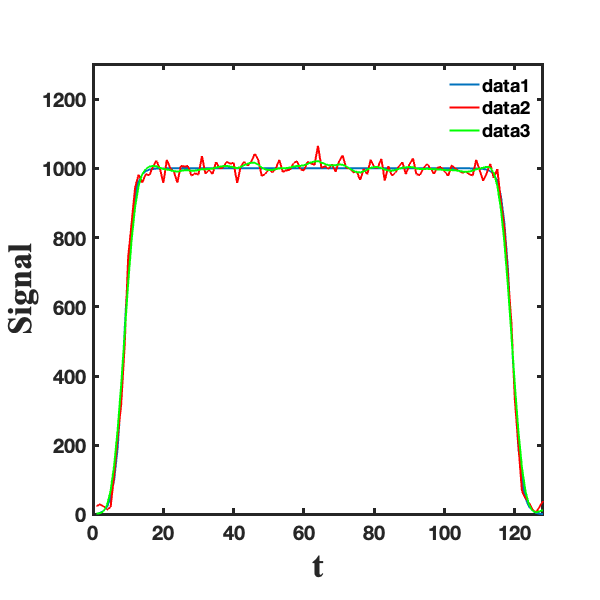


structHandler.figure = figure(9);
plot(x,b1_func, 'LineWidth', 2), axis([0 128 0 1300])

hold on
plot(x,noise_b1, 'r', 'LineWidth', 2), axis([0 128 0 1300])
plot(x,filt_b1_1d, 'g', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Delta artifact

factor = 1.25

factor = 1.2500

delta_b1 = b1_func

delta_b1 = 	1.0e+03 *

    0.0022    0.0048    0.0103    0.0223    0.0475    0.0982    0.1921    0.3419    0.5315    0.7125    0.8441    0.9220    0.9627    0.9826    0.9919    0.9963    0.9983    0.9992    0.9996    0.9998    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


delta_b1(dim/2)=delta_b1(dim/2)*factor

delta_b1 = 	1.0e+03 *

    0.0022    0.0048    0.0103    0.0223    0.0475    0.0982    0.1921    0.3419    0.5315    0.7125    0.8441    0.9220    0.9627    0.9826    0.9919    0.9963    0.9983    0.9992    0.9996    0.9998    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


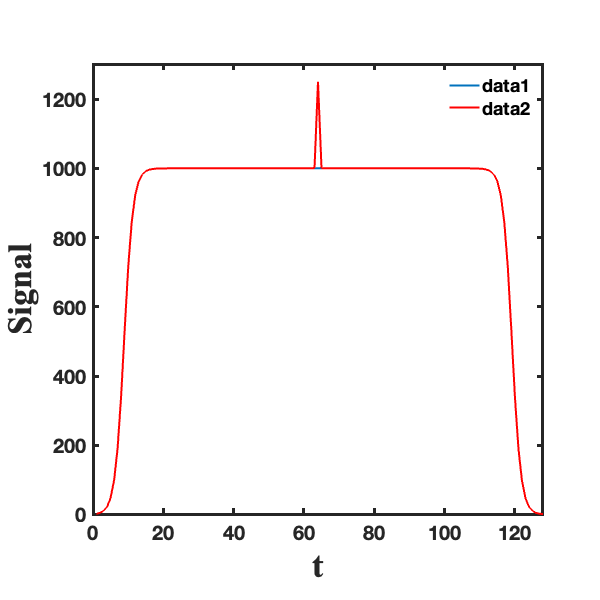


structHandler.figure = figure(10);
plot(x,b1_func, 'LineWidth', 2), axis([0 128 0 1300])

hold on
plot(x,delta_b1, 'r', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Plotly with drop down for each method

filt_b1 = filter_map()

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


data.Raw = repmat(delta_b1, dim, 1)

data = struct with fields:
    Raw: [128×128 double]



fwhm_vox = 5

fwhm_vox = 5


filt_b1.options.Smoothingfilter_sizex = fwhm_vox

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


filt_b1.options.Smoothingfilter_sizey = fwhm_vox

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


filt_b1.options.Smoothingfilter_sizez = fwhm_vox

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]



filt_b1.options.Smoothingfilter_Dimension = '2D'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


Gauss

filt_b1.options.Smoothingfilter_Type = 'gaussian'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


fit_results = filt_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


filt_b1_1d = fit_results.Filtered(1,:)

filt_b1_1d = 	1.0e+03 *

    0.0076    0.0150    0.0299    0.0575    0.1039    0.1745    0.2713    0.3904    0.5214    0.6500    0.7627    0.8512    0.9135    0.9532    0.9762    0.9884    0.9945    0.9975    0.9988    0.9995    0.9998    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


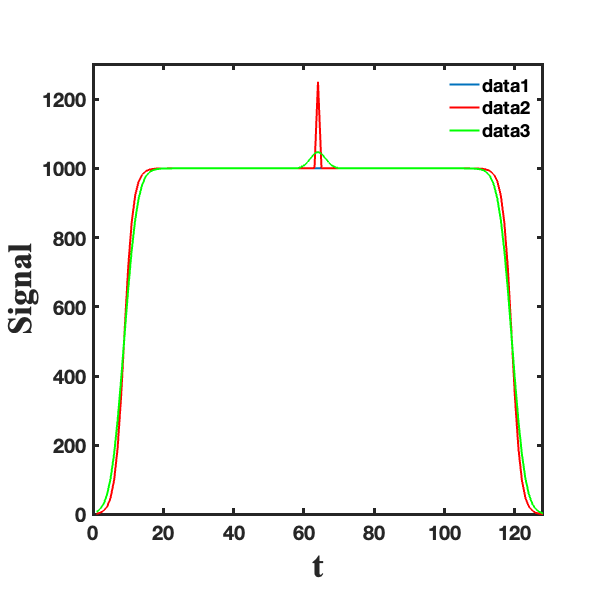


structHandler.figure = figure(11);
plot(x,b1_func, 'LineWidth', 2), axis([0 128 0 1300])

hold on
plot(x,delta_b1, 'r', 'LineWidth', 2), axis([0 128 0 1300])
plot(x,filt_b1_1d, 'g', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Median

filt_b1.options.Smoothingfilter_Type = 'median'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


fit_results = filt_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


filt_b1_1d = fit_results.Filtered(1,:)

filt_b1_1d = 	1.0e+03 *

         0         0    0.0022    0.0048    0.0103    0.0223    0.0475    0.0982    0.1921    0.3419    0.5315    0.7125    0.8441    0.9220    0.9627    0.9826    0.9919    0.9963    0.9983    0.9992    0.9996    0.9998    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


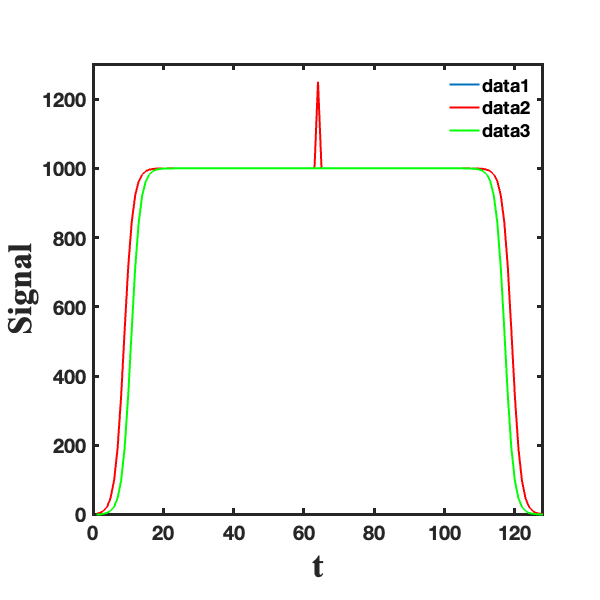


structHandler.figure = figure(12);
plot(x,b1_func, 'LineWidth', 2), axis([0 128 0 1300])

hold on
plot(x,delta_b1, 'r', 'LineWidth', 2), axis([0 128 0 1300])
plot(x,filt_b1_1d, 'g', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Poly

filt_b1.options.Smoothingfilter_Type = 'polynomial'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


fit_results = filt_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


filt_b1_1d = fit_results.Filtered(1,:)

filt_b1_1d = 	1.0e+03 *

   -0.2584   -0.1130    0.0194    0.1396    0.2487    0.3472    0.4361    0.5160    0.5876    0.6515    0.7084    0.7588    0.8032    0.8423    0.8763    0.9059    0.9314    0.9531    0.9716    0.9870    0.9998    1.0101    1.0184    1.0248    1.0296    1.0329    1.0350    1.0361    1.0363    1.0357    1.0345    1.0329    1.0308    1.0285    1.0260    1.0233    1.0205    1.0178    1.0151    1.0124    1.0099    1.0075    1.0053    1.0032    1.0013    0.9996    0.9980    0.9967    0.9955    0.9946


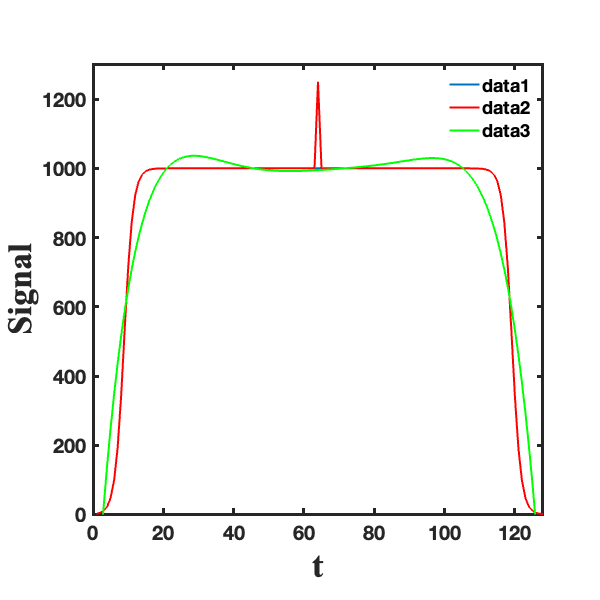


structHandler.figure = figure(13);
plot(x,b1_func, 'LineWidth', 2), axis([0 128 0 1300])

hold on
plot(x,delta_b1, 'r', 'LineWidth', 2), axis([0 128 0 1300])
plot(x,filt_b1_1d, 'g', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Spline

filt_b1.options.Smoothingfilter_Type = 'spline'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


fit_results = filt_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


filt_b1_1d = fit_results.Filtered(1,:)

filt_b1_1d = 	1.0e+03 *

   -0.0159   -0.0117   -0.0003    0.0241    0.0690    0.1416    0.2455    0.3773    0.5243    0.6682    0.7919    0.8855    0.9479    0.9842    1.0018    1.0079    1.0081    1.0060    1.0036    1.0017    1.0005    0.9999    0.9997    0.9997    0.9997    0.9998    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0001    1.0001    1.0001


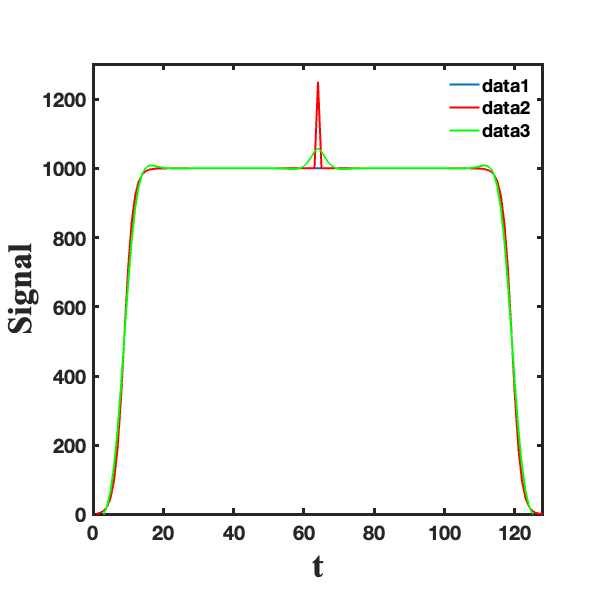


structHandler.figure = figure(14);
plot(x,b1_func, 'LineWidth', 2), axis([0 128 0 1300])

hold on
plot(x,delta_b1, 'r', 'LineWidth', 2), axis([0 128 0 1300])
plot(x,filt_b1_1d, 'g', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Edge case

step_b1 = b1_func

step_b1 = 	1.0e+03 *

    0.0022    0.0048    0.0103    0.0223    0.0475    0.0982    0.1921    0.3419    0.5315    0.7125    0.8441    0.9220    0.9627    0.9826    0.9919    0.9963    0.9983    0.9992    0.9996    0.9998    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


step_b1(round(3/4*dim):end)=0

step_b1 = 	1.0e+03 *

    0.0022    0.0048    0.0103    0.0223    0.0475    0.0982    0.1921    0.3419    0.5315    0.7125    0.8441    0.9220    0.9627    0.9826    0.9919    0.9963    0.9983    0.9992    0.9996    0.9998    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


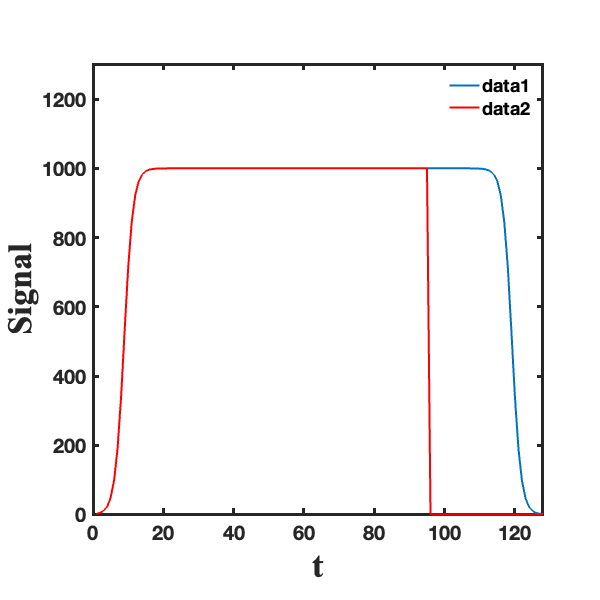


structHandler.figure = figure(15);

hold on
plot(x,step_b1, 'r', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Plotly with drop down for each method

filt_b1 = filter_map()

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


data.Raw = repmat(step_b1, dim, 1)

data = struct with fields:
    Raw: [128×128 double]



fwhm_vox = 5

fwhm_vox = 5


filt_b1.options.Smoothingfilter_sizex = fwhm_vox

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


filt_b1.options.Smoothingfilter_sizey = fwhm_vox

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


filt_b1.options.Smoothingfilter_sizez = fwhm_vox

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]



filt_b1.options.Smoothingfilter_Dimension = '2D'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


Gauss

filt_b1.options.Smoothingfilter_Type = 'gaussian'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


fit_results = filt_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


filt_b1_1d = fit_results.Filtered(1,:)

filt_b1_1d = 	1.0e+03 *

    0.0076    0.0150    0.0299    0.0575    0.1039    0.1745    0.2713    0.3904    0.5214    0.6500    0.7627    0.8512    0.9135    0.9532    0.9762    0.9884    0.9945    0.9975    0.9988    0.9995    0.9998    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


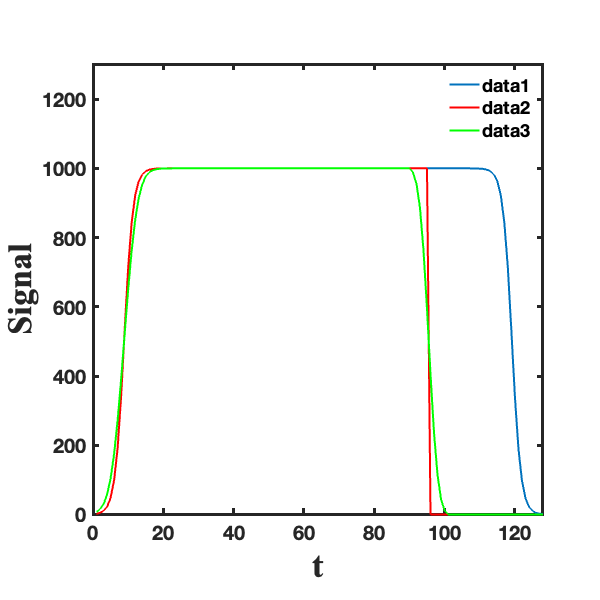


structHandler.figure = figure(16);

hold on
plot(x,step_b1, 'r', 'LineWidth', 2), axis([0 128 0 1300])
plot(x,filt_b1_1d, 'g', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Median

filt_b1.options.Smoothingfilter_Type = 'median'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


fit_results = filt_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


filt_b1_1d = fit_results.Filtered(1,:)

filt_b1_1d = 	1.0e+03 *

         0         0    0.0022    0.0048    0.0103    0.0223    0.0475    0.0982    0.1921    0.3419    0.5315    0.7125    0.8441    0.9220    0.9627    0.9826    0.9919    0.9963    0.9983    0.9992    0.9996    0.9998    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


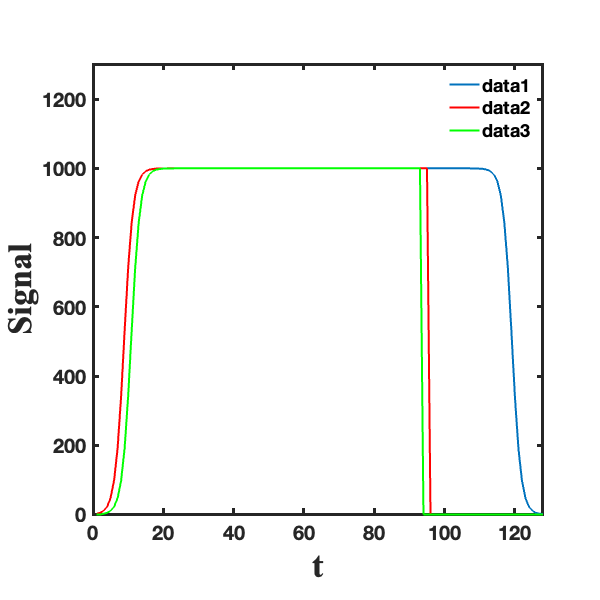


structHandler.figure = figure(17);

hold on
plot(x,step_b1, 'r', 'LineWidth', 2), axis([0 128 0 1300])
plot(x,filt_b1_1d, 'g', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Poly

filt_b1.options.Smoothingfilter_Type = 'polynomial'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


fit_results = filt_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


filt_b1_1d = fit_results.Filtered(1,:)

filt_b1_1d = 	1.0e+03 *

   -0.3155   -0.1536   -0.0065    0.1266    0.2467    0.3546    0.4513    0.5375    0.6140    0.6815    0.7408    0.7925    0.8373    0.8757    0.9083    0.9357    0.9584    0.9768    0.9915    1.0028    1.0111    1.0168    1.0203    1.0219    1.0219    1.0206    1.0181    1.0149    1.0110    1.0067    1.0021    0.9975    0.9929    0.9885    0.9844    0.9806    0.9774    0.9746    0.9725    0.9709    0.9700    0.9698    0.9702    0.9714    0.9731    0.9755    0.9785    0.9821    0.9862    0.9908


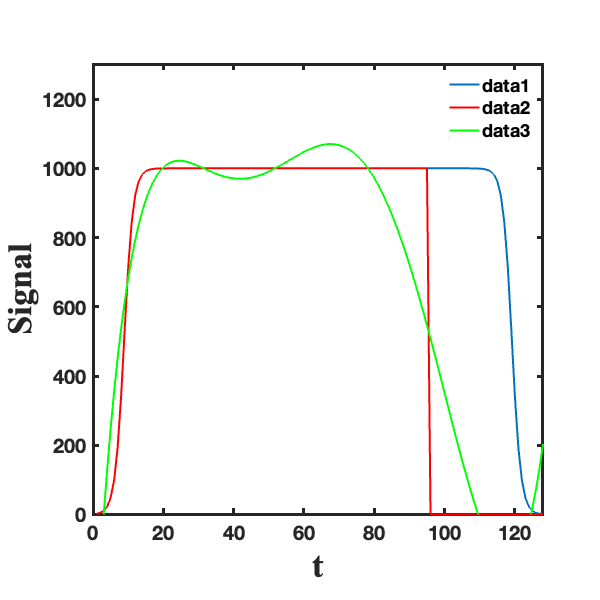


structHandler.figure = figure(18);

hold on
plot(x,step_b1, 'r', 'LineWidth', 2), axis([0 128 0 1300])
plot(x,filt_b1_1d, 'g', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off

Spline

filt_b1.options.Smoothingfilter_Type = 'spline'

filt_b1 =   filter_map with properties:

    MRIinputs: {'Raw'  'Mask'}
       xnames: {}
    voxelwise: 0
         Prot: [1×1 struct]
      version: [2 4 2]
    ModelName: 'filter_map'
      buttons: {'PANEL'  'Smoothing filter'  [6]  'Type'  {1×4 cell}  'Dimension'  {1×2 cell}  '##size x'  [3]  '##size y'  [3]  '##size z'  [3]  'order'  [6]}
      options: [1×1 struct]


fit_results = filt_b1.fit(data)

fit_results = struct with fields:
    Filtered: [128×128 double]


filt_b1_1d = fit_results.Filtered(1,:)

filt_b1_1d = 	1.0e+03 *

   -0.0159   -0.0117   -0.0003    0.0241    0.0690    0.1416    0.2455    0.3773    0.5243    0.6682    0.7919    0.8855    0.9479    0.9842    1.0018    1.0079    1.0081    1.0060    1.0036    1.0017    1.0005    0.9999    0.9997    0.9997    0.9997    0.9998    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


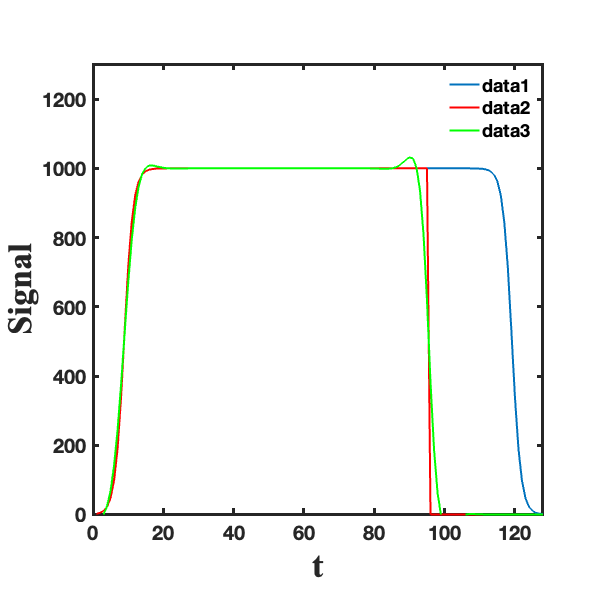


structHandler.figure = figure(19);

hold on
plot(x,step_b1, 'r', 'LineWidth', 2), axis([0 128 0 1300])
plot(x,filt_b1_1d, 'g', 'LineWidth', 2), axis([0 128 0 1300])

structHandler.xlabel = xlabel('t');
structHandler.ylabel = ylabel('Signal');
figureProperties_plot(structHandler)
hold off